clear
load("H:/result/2018_12_13_IMCL_direct_estimation_single_element/wire/2018_12_18/2018_12_18_all_result.mat")

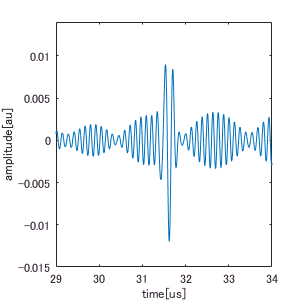

interp_t_array = interp1(kgrid.t_array,linspace(1,num_sample,num_sample*4)','spline');
figure;
plot(interp_t_array*1e6,rfdata_echo_only(:,1));
ylim([-0.015 0.014])
xlim([29 34])
xlabel('time[us]')
ylabel('amplitude[au]')
savefig('H:/result/2018_12_13_IMCL_direct_estimation_single_element/discussion/wire_rf.fig')
exportfig("H:/result/2018_12_13_IMCL_direct_estimation_single_element/discussion/wire_rf",'png',[300,300])

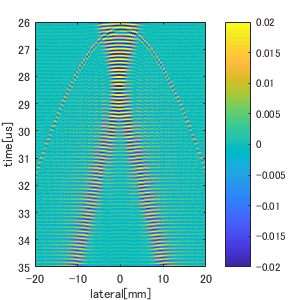


figure;
imagesc(t_pos(1,:)*1e3,interp_t_array*1e6,rfdata_echo_only);
colorbar
caxis([-0.02 0.02])
ylim([26 35])
xlabel('lateral[mm]')
ylabel('time[us]')
savefig('H:/result/2018_12_13_IMCL_direct_estimation_single_element/discussion/wire_rf2.fig')
exportfig("H:/result/2018_12_13_IMCL_direct_estimation_single_element/discussion/wire_rf2",'png',[300,300])

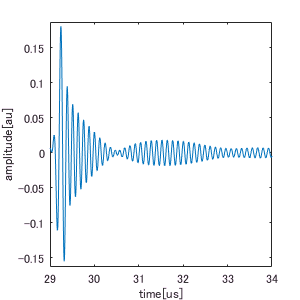


load("H:/result/2018_12_13_IMCL_direct_estimation_single_element/2layer/2018_12_19/2018_12_19_all_result.mat")
figure;
plot(interp_t_array*1e6,rfdata_echo_only(:,1));
ylim([-0.163 0.187])
xlim([29 34])
xlabel('time[us]')
ylabel('amplitude[au]')
savefig('H:/result/2018_12_13_IMCL_direct_estimation_single_element/discussion/2layer_rf.fig')
exportfig("H:/result/2018_12_13_IMCL_direct_estimation_single_element/discussion/2layer_rf",'png',[300,300])

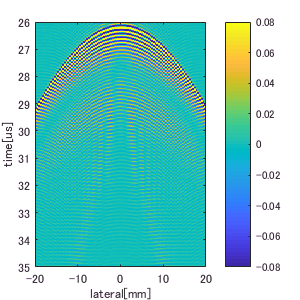


figure;
imagesc(t_pos(1,:)*1e3,interp_t_array*1e6,rfdata_echo_only);
colorbar
caxis([-0.08 0.08])
ylim([26 35])
xlabel('lateral[mm]')
ylabel('time[us]')
savefig('H:/result/2018_12_13_IMCL_direct_estimation_single_element/discussion/2layer_rf2.fig')
exportfig("H:/result/2018_12_13_IMCL_direct_estimation_single_element/discussion/2layer_rf2",'png',[300,300])